## **Driver test program to check Clothoids library**

**Test G2 clothoid**

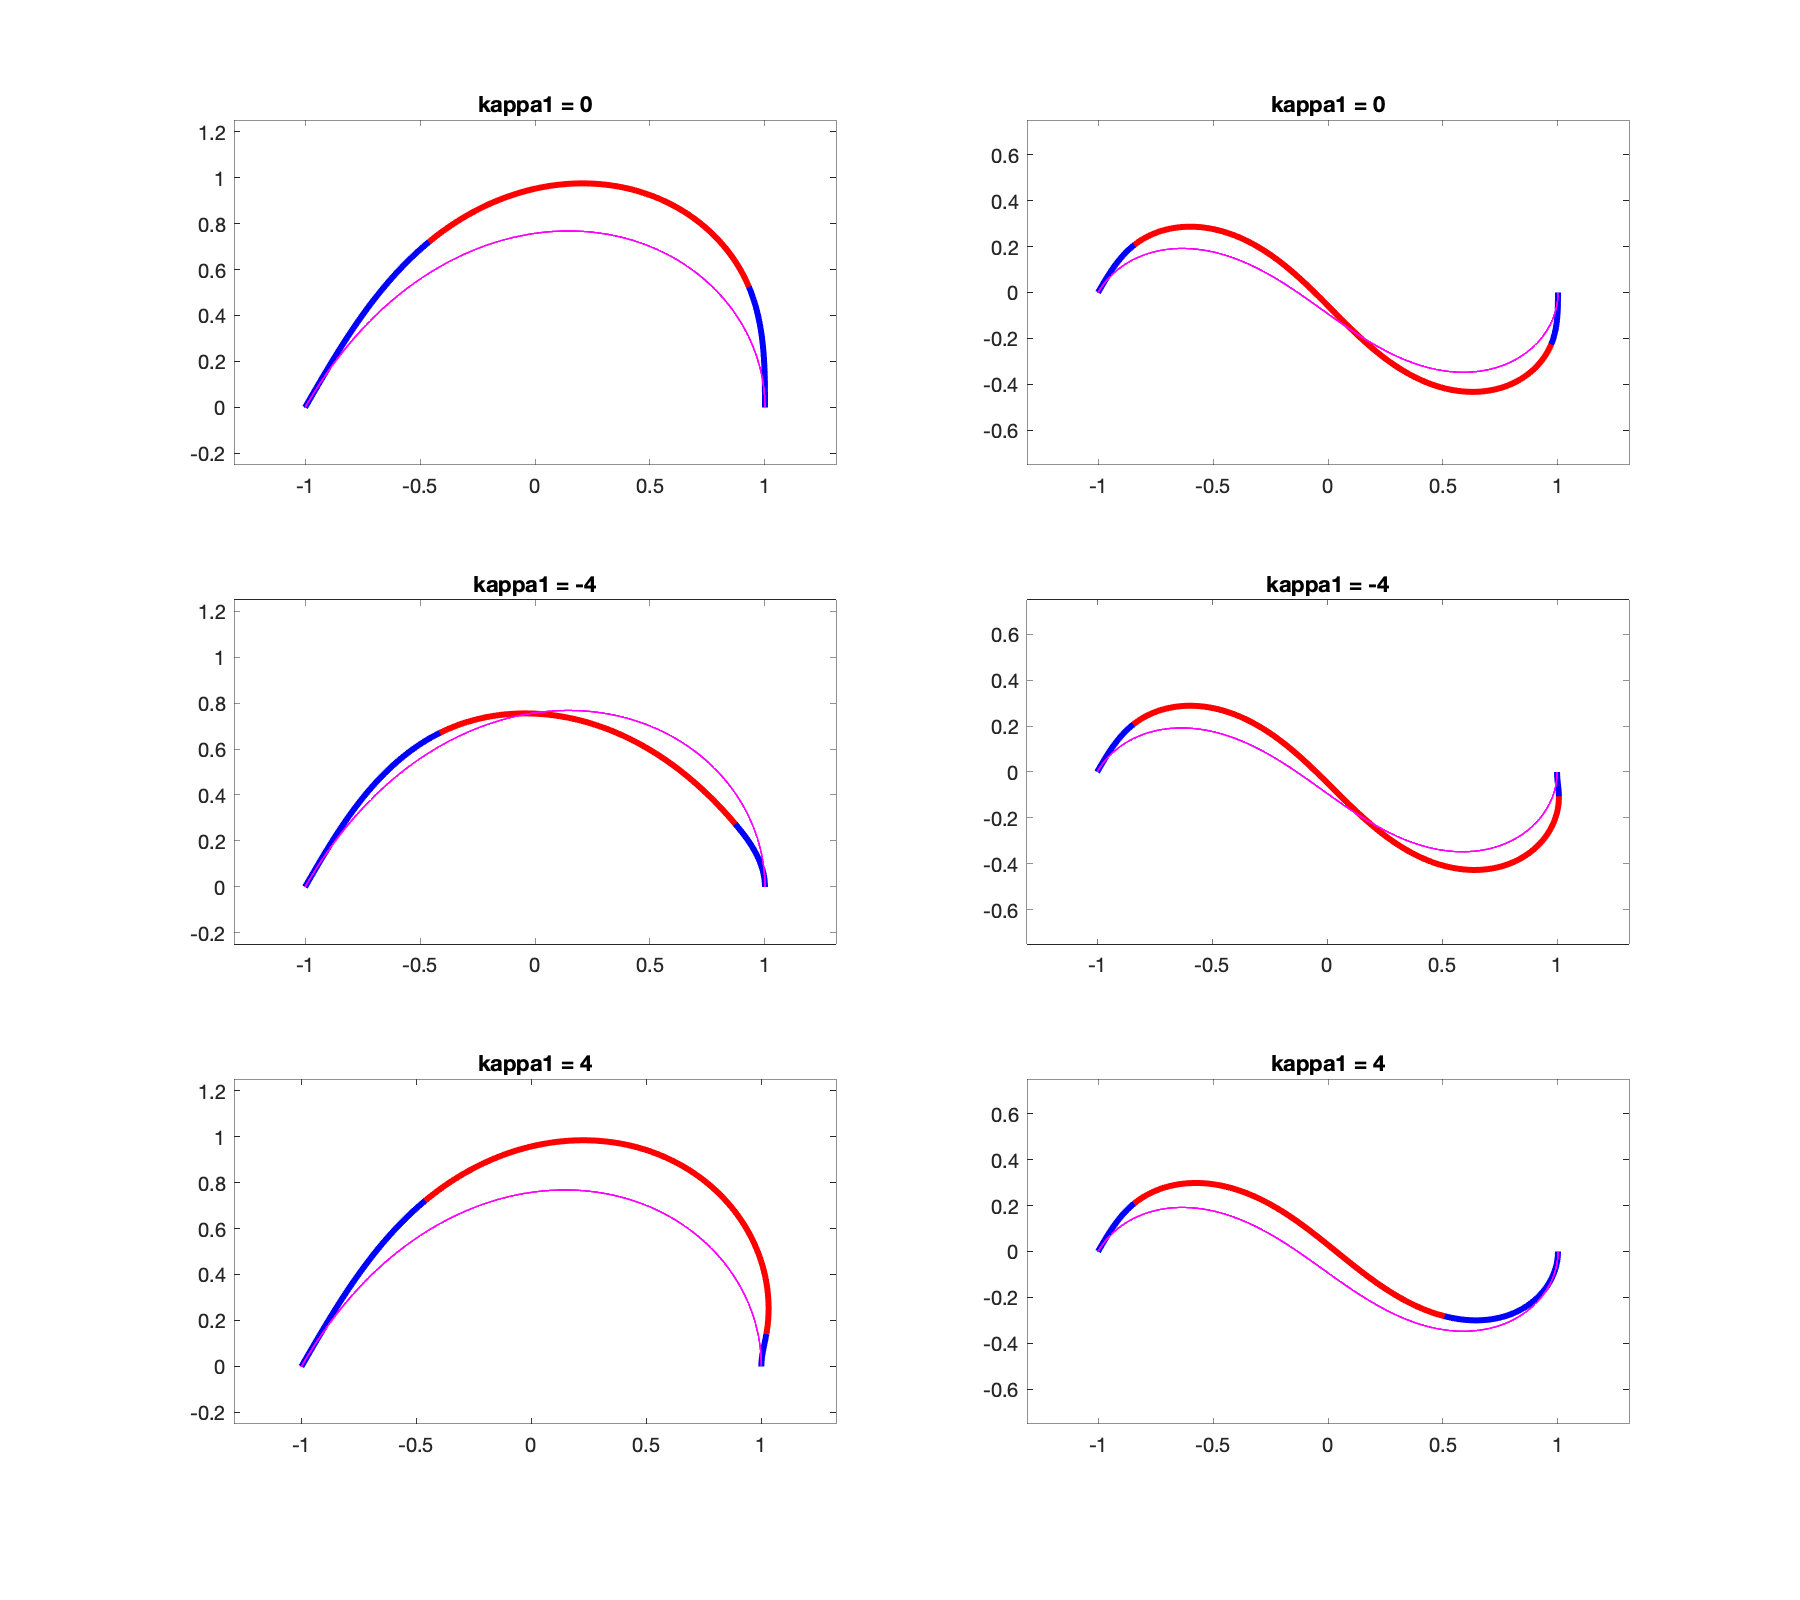

close all;
format long;
x0 = -1;
y0 = 0;
x1 = 1;
y1 = 0;

theta0 = pi/3;
kappa0 = 0;
theta1 = [-pi/2,pi/2,-pi/2,pi/2,-pi/2,pi/2,];% [-pi/2,-pi/8,0,pi/4,pi/2];
kappa1 = [0,0,-4,-4,4,4];

close all;
figure('Position',[1,1,900,800]);

AXEL = [-1 1 -0.25 1.25];
AXER = [-1 1 -0.75 0.75];

S = ClothoidList();
C = ClothoidCurve();

for k=1:6
  subplot(3,2,k);
  %subaxis(3,2,k, 'Spacing', 0.01, 'Padding', 0.02, 'Margin', 0.02);
  %axis tight;
  
  iter = S.build_3arcG2(x0,y0,theta0,kappa0,x1,y1,theta1(k),kappa1(k));
  if iter >= 0
    S.plot();
    hold on
    if mod(k,2) == 0
      axis(AXER);
    else
      axis(AXEL);
    end
    xlim([-1.2 1.2])
    axis equal;
    title( sprintf('kappa1 = %g',kappa1(k))); 
    iter = C.build_G1(x0,y0,theta0,x1,y1,theta1(k));
    C.plot(1000,'-m','Linewidth',1);
  else
    disp('errore');
  end
  set(gca,'DataAspectRatio',[1,1,1]);
  if false
    set(gca,'XTick',[-2,-1.5,-1,-0.5,0,0.5,1,1.5,2]);
    set(gca,'XTickLabel',{'$-2$','$-1.5$','$-1$','$-0.5$','$0$','$0.5$','$1$','$1.5$','$2$'});
    set(gca,'YTick',[-2,-1.5,-1,-0.5,0,0.5,1,1.5,2]);
    set(gca,'YTickLabel',{'$-2$','$-1.5$','$-1$','$-0.5$','$0$','$0.5$','$1$','$1.5$','$2$'});
  end
end